%input
f0 = 100; % center freq
dBgain = 2 % gain

dBgain = 2

Qfactor = 0.9; 

fsample = 44000; % sampling frequency Nyquist = 22000 Hz
N = 44000;
fcut_Norm = f0 / (fsample/2)

fcut_Norm = 0.0045


% Angle to the freq
w0 = 2*pi*(f0/fsample) 

w0 = 0.0143


% A variable only used in peaking and shelving
A = sqrt(20*log10(dBgain));

% Alpha with Q factor
alpha = (sin(w0)) / (2*Qfactor);

% Peak filter Coeff b
b0 = 1 + alpha*A; 
b1 = -2*cos(w0); 
b2 = 1 - alpha*A;
b = [b0, b1, b2] 

b =     1.0195   -1.9998    0.9805



% Peak filter Coeff a
a0 = 1+alpha/A; 
a1 = -2*cos(w0); 
a2 = 1-alpha/A;
a = [a0, a1, a2] 

a =     1.0032   -1.9998    0.9968


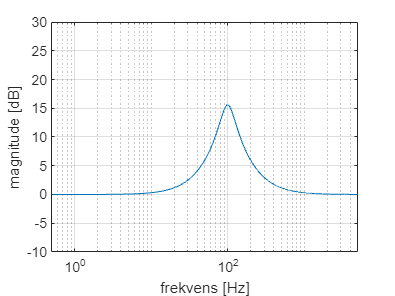


h = freqz(b,a,fsample); 

%Frekvens akse i log 
f_oploesning = fsample/N; % frekvens opløsning
f_akse = (0:f_oploesning:fsample - f_oploesning); 
X_dB_norm = 20*log10(abs(h));

semilogx(f_akse(1:end/2)/2, X_dB_norm(1:end/2))
%plot(f_akse(1:end/2)/2, abs(h(1:end/2)))
grid on 
xlim([0, 5000]) 
ylim([-10, 30]) 
xlabel("frekvens [Hz]") 
ylabel("magnitude [dB]")